#### Clear environment

clear
close all
clc

# Non linear equations

# Part 1 - Growth Model


$$p(t) = \frac{p_m}{1 + (\frac{p_m}{p_0} - 1) e^{-Kp_mt}}$$


given $K = 2*10^-6$ and $p_0 = p(0) = 100$

after plotting $t_1 = 60$ we have $p_1 = p(t_1) = 25000$

solving for $p_m$:


$$(1 + (\frac{p_m}{p_0} - 1) e^{-Kp_mt})p_1 = p_m$$



$$(1 + (\frac{p_m}{p_0} - 1) e^{-Kp_mt})p_1 - p_m = 0$$



$$f_{p_m} = p_1(1 + (\frac{p_m}{p_0} - 1) e^{-Kp_mt}) - p_m$$


with derivative:


$$f'_{p_m} = -1 + \frac{p_1 e^{-K p_mt}(1 + K(-p_m + p_0)t)}{p_0}$$


The function as a code are defined at the end of the script.

## Functions definition

% interval to plot
a = 0; b = 100000;

% functions parameters:
K = 2e-6; p0 = 100; t1 = 60; p1 = 25000;

% function for p_m:
fun = @(pm) logistic_growth_pm(pm, K, p0, t1, p1);
fun_prime = @(pm) logistic_growth_pm_prime(pm, K, p0, t1, p1);

% termination criteria
tolerance=1e-14;
kmax=1e3;

## plot function

f = figure();
f.Name = 'Functions';
f.NumberTitle = 'off';
f.Position = [0, 1000, 800, 600];

subplot(2, 2, 1);
fplot(fun, [a, b]);

grid on;

title('$f: p_m \to f(p_m) = linear\ equation\ of\ p_m$', 'interpreter','latex');
subtitle(['as p(', num2str(t1), ') = ', num2str(p1)], 'interpreter','latex');
xlabel("p_m"); ylabel("f(p_m)");
xline(0, ':k'); yline(0, ':k');

subplot(2, 2, 3);
fplot(fun_prime, [a, b]);

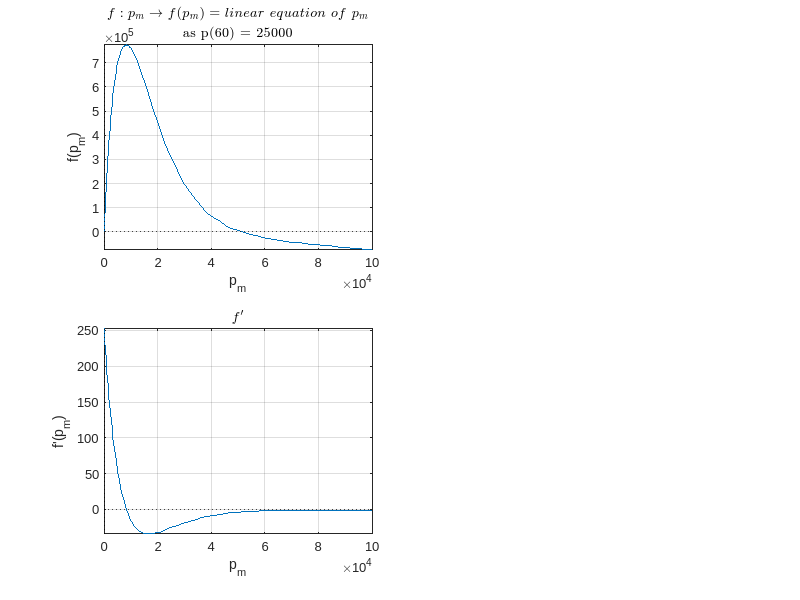

grid on;
title("$f'$", 'interpreter','latex');
xlabel("p_m"); ylabel("f'(p_m)");
xline(0, ':k'); yline(0, ':k');

## Approximate $p_m$ 

### Newton method

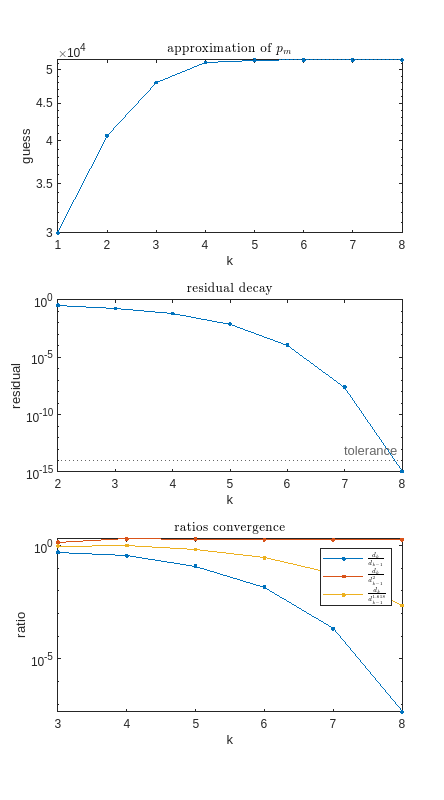

x0 = 30000;
pm = newton( ...
    fun, fun_prime, x0, kmax, tolerance ...
);

### Fixed Secant method

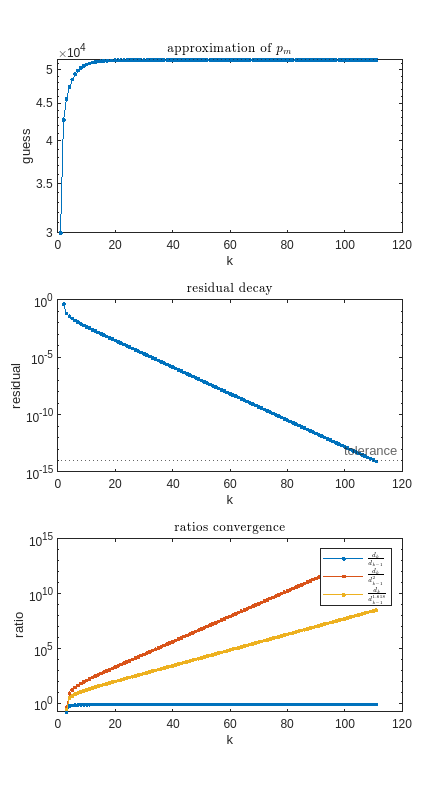

x1 = 35000;
pm_fx_secant = fxsecant( ...
    fun, x0, x1, kmax, tolerance ...
);

### Secant method

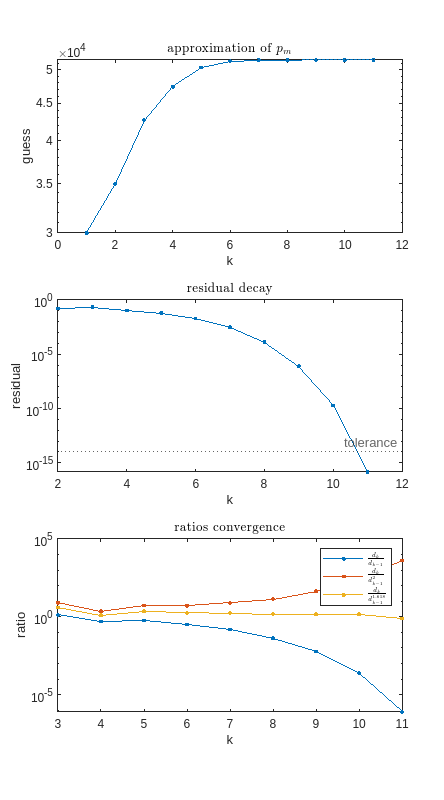

pm_secant = secant( ...
    fun, x0, x1, kmax, tolerance ...
);

#### Check for convergence of the three methods into a single solution

convergence_tolerance = 1e-8;
if abs(pm - pm_fx_secant) > convergence_tolerance || ...
    abs(pm - pm_secant) > convergence_tolerance
    error("the three methods doesn't converge");
end

The final solution is printed out

disp(['final approximation of p_m: ', num2str(pm)]);

final approximation of p_m: 51528.5997


## Define logistic growth model

% interval to plot
a = 0; b = 250;

% function definition
p_fun = @(t) logistic_growth(t, pm, p0, K);

figure(f);
subplot(2, 2, 2);
fplot(p_fun, [a, b]);

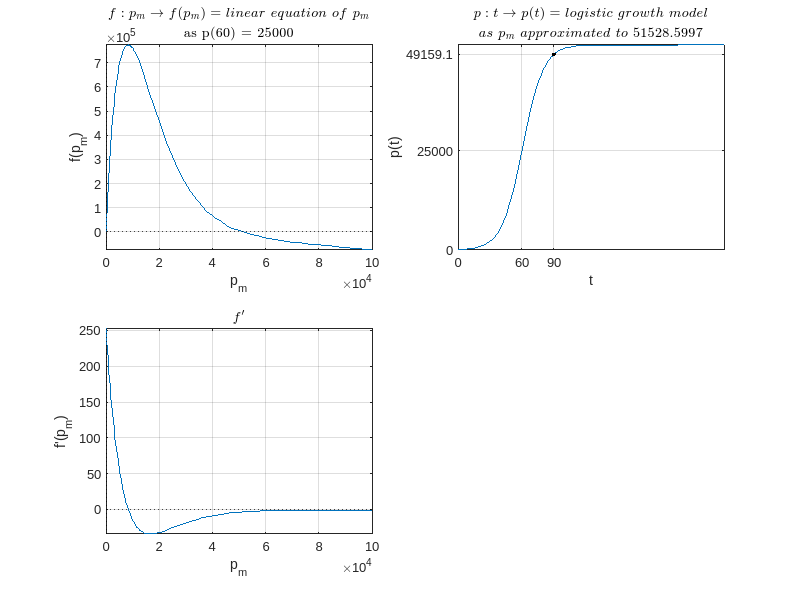

grid on;
title('$p: t \to p(t) = logistic\ growth\ model$', 'interpreter', 'latex');
subtitle(['$as\ p_m\ approximated\ to\ ', num2str(pm), '$'], 'interpreter', 'latex');
xlabel("t"); ylabel("p(t)");
hold on;

T = 90;
res = p_fun(T);
yticks([0, p1, res, pm]); yticklabels([0, p1, res, pm]);
xticks([0, t1, T]); xticklabels([0, t1, T]);
plot(T, res, 'k.');
hold off;


disp(['p(', num2str(T), ') = ', num2str(res)]);

p(90) = 49159.0667


## Picard Iteration

If we re-formulate the problem we can find a function g such that:


$$g_{p_m} = p_1(1 + (\frac{p_m}{p_0} - 1)e^{-Kp_mt})$$


with derivative


$$g'_{p_m} = \frac{p_1e^{-Kp_mt}(1 + K(-p_m+p_0)t)}{p_0}$$


that converges if


$$\frac{p_1e^{-Kp_mt}(1 + K(-p_m+p_0)t)}{p_0} < 1$$


that, after replacing the constant and resolving for $p_m$ it gives: $p_m > 238886$.

Since this value is above the real $p_m$ this fixed-point problem could never converge.

# Part 2 - Non linear systems

## System definition

f1 = @(x, y) x^2 + y^2 - 1;
f2 = @(x, y) sin(pi/2 * x) + y^3;

Given the two sytem functions, define the two mesh along with the plane $z = 0$

x1_range = -2:0.1:2;
x2_range = -2:0.1:2;
[X1, X2] = meshgrid(x1_range, x2_range);

Y1 = zeros(size(X1));
Y2 = zeros(size(X1));
Z0 = zeros(size(X1));
for i = 1:numel(X1)
    Y1(i) = f1(X1(i), X2(i));
    Y2(i) = f2(X1(i), X2(i));
end

## Find zeros

termination criteria

kmax = 1e3;
tolerance = 1e-8;

Initial points $x_{0A}$ and $x_{0B}$

x0A = [1; 1];
x0B = [-1; 1];

### Newton method

[zeroA, xA, kA, aeA, reA] = newtonsys( ...
    @sys, @jac, x0A, kmax, tolerance ...
);

[zeroB, xB, kB, aeB, reB] = newtonsys( ...
    @sys, @jac, x0B, kmax, tolerance ...
);

#### Plots

f = figure();
f.Name = 'Non-linear system: Newton-Raphson method';
f.NumberTitle = 'off';
f.Position = [0, 0, 800, 1300];

Plot 1: approximations over the systems

subplot(3, 1, 1);
d1 = surf(X1, X2, Y1, 'FaceColor', 'r');
hold on;
d2 = surf(X1, X2, Y2, 'FaceColor', 'b');
hold on;
mesh(X1, X2, Z0);
title('zero approximations with Newton method', 'interpreter', 'latex');
xlabel('x1'); ylabel('x2'); zlabel('y');

% Draw x lines and the zero points, green for the first point, black for the second

z_values = linspace(-10, 10, 2);
for i = 1:kA
    x_values = xA{i}(1) * ones(size(z_values));
    y_values = xA{i}(2) * ones(size(z_values));

    plot3(x_values, y_values, z_values, 'g', 'LineWidth', 2);
end
d3 = scatter3(zeroA(1), zeroA(2), 0, 'g', 'filled');

for i = 1:kB
    x_values = xB{i}(1) * ones(size(z_values));
    y_values = xB{i}(2) * ones(size(z_values));

    plot3(x_values, y_values, z_values, 'k', 'LineWidth', 2);
end
d4 = scatter3(zeroB(1), zeroB(2), 0, 'k', 'filled');

legend([d1, d2, d3, d4], ["$x^2 + y^2 = 1$", "$sin(\frac \pi 2 x) + y^3 = 0$", ...
    "first zero approximation", "second zero approximation"], ...
    'Location','northeast', 'interpreter', 'latex');

Plot 2: convergences errors

subplot(3, 1, 2);
semilogy(reA, '.-');
title(['residual decay with $x0 = (', num2str(x0A(1)), ', ', num2str(x0A(1)), ')^T$'], ...
    'interpreter', 'latex');
xlabel("k"); ylabel("residual");
yline(tolerance, ':', 'tolerance');

Plot 3: convergence ratios

Here we compute the ratios $\frac{d_k}{d_{k-1}}$ and $\frac{d_k}{d_{k-1}^2}$ to be able to understand the asympthotic behaviour

ratio1 = reA(2:end) ./ reA(1:end-1);
ratio1 = [Inf ratio1];

ratio2 = reA(2:end) ./ (reA(1:end-1) .^ 2);
ratio2 = [Inf ratio2];

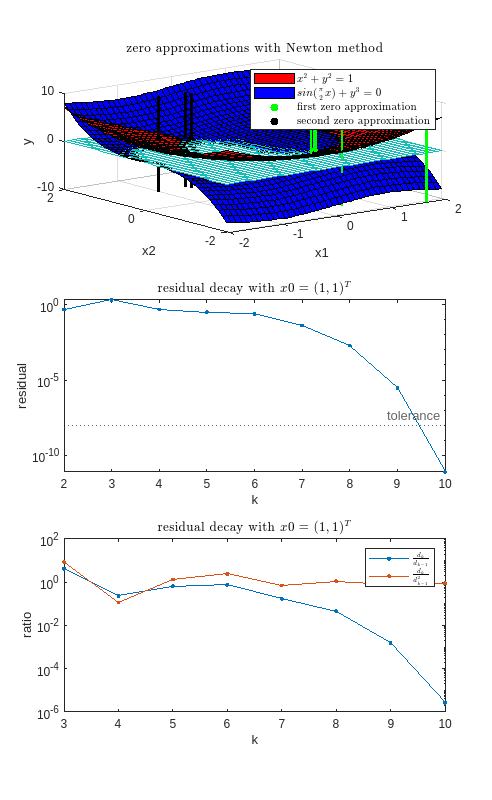

subplot(3, 1, 3);
semilogy(1:length(ratio1), ratio1, '.-', ...
        1:length(ratio2), ratio2, '.-');
title(['residual decay with $x0 = (', num2str(x0A(1)), ', ', num2str(x0A(1)), ')^T$'], ...
    'interpreter', 'latex');
legend('$\frac{d_k}{d_{k-1}}$', ...
        '$\frac{d_k}{d_{k-1}^2}$', ...
         'interpreter', 'latex');
xlabel("k"); ylabel("ratio");

Print results in a table

varNames = ["k", "increment (normalized)", "relative increment (normilized)", "ratio p = 1", "ratio p = 2"];
T = table((0:(kA - 1))', aeA', reA', ratio1', ratio2', 'VariableNames', varNames);
writetable(T, 'newtonsys_A.csv', 'Delimiter',';');

ratio1 = reB(2:end) ./ reB(1:end-1);
ratio1 = [Inf ratio1];

ratio2 = reB(2:end) ./ (reB(1:end-1) .^ 2);
ratio2 = [Inf ratio2];

varNames = ["k", "increment (normalized)", "relative increment (normilized)", "ratio p = 1", "ratio p = 2"];
T = table((0:(kB - 1))', aeB', reB', ratio1', ratio2', 'VariableNames', varNames);
writetable(T, 'newtonsys_B.csv', 'Delimiter',';');

And finally we log the final values for reference

disp('zero approximations with Newton method');

zero approximations with Newton method


disp(['first zero = (', num2str(zeroA(1)), ', ', num2str(zeroA(2)), ...
    ') from x0 = (', num2str(x0A(1)), ', ', num2str(x0A(1)), ...
    ') with ', num2str(kA), ' iterations']);

first zero = (0.4761, -0.87939) from x0 = (1, 1) with 10 iterations


disp(['second zero = (', num2str(zeroB(1)), ', ', num2str(zeroB(2)), ...
    ') from x0 = (', num2str(x0B(1)), ', ', num2str(x0B(1)), ...
    ') with ', num2str(kB), ' iterations']);

second zero = (-0.4761, 0.87939) from x0 = (-1, -1) with 7 iterations


### Broyden method with $B^{(0)} = I$

B0 = eye(2);

[zeroA, xA, kA, aeA, reA] = broydensys( ...
    @sys, B0, x0A, kmax, tolerance ...
);

[zeroB, xB, kB, aeB, reB] = broydensys( ...
    @sys, B0, x0B, kmax, tolerance ...
);

#### Plots

f = figure();
f.Name = 'Non-linear system: Broyden method';
f.NumberTitle = 'off';
f.Position = [800, 0, 1600, 1300];

Plot 1: approximations over the systems

subplot(3, 2, 1);
d1 = surf(X1, X2, Y1, 'FaceColor', 'r');
hold on;
d2 = surf(X1, X2, Y2, 'FaceColor', 'b');
hold on;
mesh(X1, X2, Z0);
title('zero approximations with Broyden method with $\textbf{B}^{(0)} = \textbf{I}$', ...
  'interpreter', 'latex');
xlabel('x1'); ylabel('x2'); zlabel('y');

% Draw x lines and the zero points, green for the first point, black for the second

z_values = linspace(-10, 10, 2);
for i = 1:kA
    x_values = xA{i}(1) * ones(size(z_values));
    y_values = xA{i}(2) * ones(size(z_values));

    plot3(x_values, y_values, z_values, 'g', 'LineWidth', 2);
end
d3 = scatter3(zeroA(1), zeroA(2), 0, 'g', 'filled');

for i = 1:kB
    x_values = xB{i}(1) * ones(size(z_values));
    y_values = xB{i}(2) * ones(size(z_values));

    plot3(x_values, y_values, z_values, 'k', 'LineWidth', 2);
end
d4 = scatter3(zeroB(1), zeroB(2), 0, 'k', 'filled');

legend([d1, d2, d3, d4], ["$x^2 + y^2 = 1$", "$sin(\frac \pi 2 x) + y^3 = 0$", ...
    "first zero approximation", "second zero approximation"], ...
    'Location','northeast', 'interpreter', 'latex');

Plot 2: convergences errors

subplot(3, 2, 3);
semilogy(reA, '.-');
title(['residual decay with $x0 = (', ...
    num2str(x0A(1)), ', ', num2str(x0A(1)), ...
    ')^T$ and $\textbf{B}^{(0)} = \textbf{I}$' ...
    ], 'interpreter', 'latex');
xlabel("k"); ylabel("residual");
yline(tolerance, ':', 'tolerance');


Plot 3: convergence ratios

ratio1 = reA(2:end) ./ reA(1:end-1);
ratio1 = [Inf ratio1];

ratio2 = reA(2:end) ./ (reA(1:end-1) .^ 2);
ratio2 = [Inf ratio2];

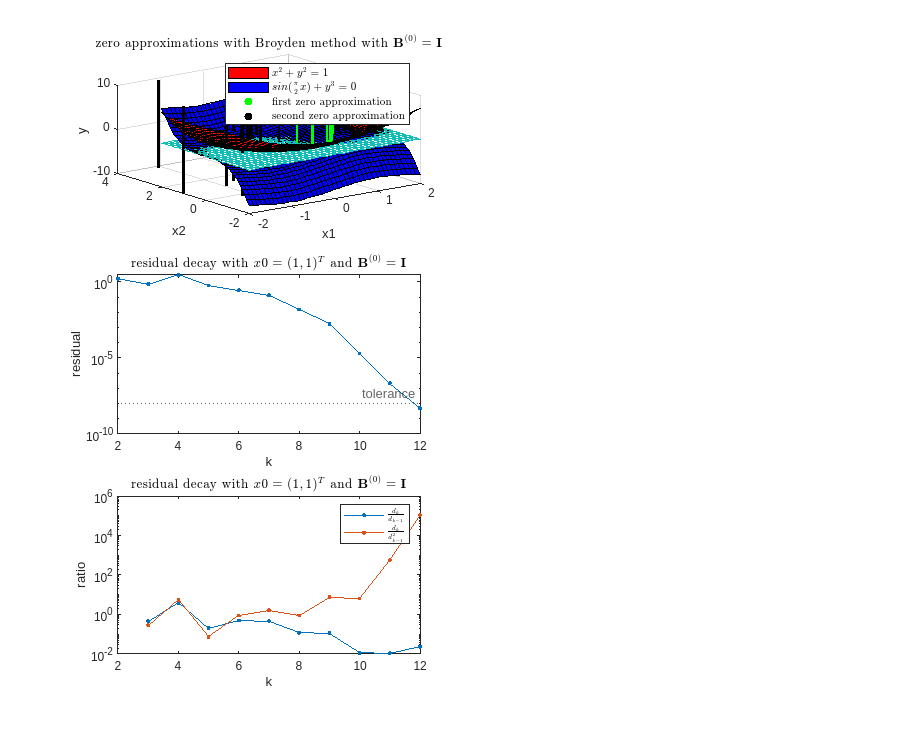

subplot(3, 2, 5);
semilogy(1:length(ratio1), ratio1, '.-', ...
        1:length(ratio2), ratio2, '.-');
title(['residual decay with $x0 = (', ...
    num2str(x0A(1)), ', ', num2str(x0A(1)), ...
    ')^T$ and $\textbf{B}^{(0)} = \textbf{I}$' ...
    ], 'interpreter', 'latex');
legend('$\frac{d_k}{d_{k-1}}$', ...
        '$\frac{d_k}{d_{k-1}^2}$', ...
         'interpreter', 'latex');
xlabel("k"); ylabel("ratio");

Print results in a table

varNames = ["k", "increment (normalized)", "relative increment (normilized)", "ratio p = 1", "ratio p = 2"];
T = table((0:(kA - 1))', aeA', reA', ratio1', ratio2', 'VariableNames', varNames);
writetable(T, 'broydensys_B=I_A.csv', 'Delimiter',';');

ratio1 = reB(2:end) ./ reB(1:end-1);
ratio1 = [Inf ratio1];

ratio2 = reB(2:end) ./ (reB(1:end-1) .^ 2);
ratio2 = [Inf ratio2];

varNames = ["k", "increment (normalized)", "relative increment (normilized)", "ratio p = 1", "ratio p = 2"];
T = table((0:(kB - 1))', aeB', reB', ratio1', ratio2', 'VariableNames', varNames);
writetable(T, 'broydensys_B=I_B.csv', 'Delimiter',';');

Log the final values

disp('zero approximations with Broyden method with B0 = I');

zero approximations with Broyden method with B0 = I


disp(['first zero = (', num2str(zeroA(1)), ', ', num2str(zeroA(2)), ...
    ') from x0 = (', num2str(x0A(1)), ', ', num2str(x0A(1)), ...
    ') with ', num2str(kA), ' iterations']);

first zero = (0.4761, -0.87939) from x0 = (1, 1) with 12 iterations


disp(['second zero = (', num2str(zeroB(1)), ', ', num2str(zeroB(2)), ...
    ') from x0 = (', num2str(x0B(1)), ', ', num2str(x0B(1)), ...
    ') with ', num2str(kB), ' iterations']);

second zero = (-0.4761, 0.87939) from x0 = (-1, -1) with 23 iterations


### Broyden method with $B^{(0)} = 2I$

B0 = 2 * eye(2);

[zeroA, xA, kA, aeA, reA] = broydensys( ...
    @sys, B0, x0A, kmax, tolerance ...
);

[zeroB, xB, kB, aeB, reB] = broydensys( ...
    @sys, B0, x0B, kmax, tolerance ...
);

#### Plots

Plot 1: approximations over the systems

subplot(3, 2, 2);
d1 = surf(X1, X2, Y1, 'FaceColor', 'r');
hold on;
d2 = surf(X1, X2, Y2, 'FaceColor', 'b');
hold on;
mesh(X1, X2, Z0);
title('zero approximations with Broyden method with $\textbf{B}^{(0)} = 2\textbf{I}$', ...
  'interpreter', 'latex');
xlabel('x1'); ylabel('x2'); zlabel('y');

% Draw x lines and the zero points, green for the first point, black for the second

z_values = linspace(-10, 10, 2);
for i = 1:kA
    x_values = xA{i}(1) * ones(size(z_values));
    y_values = xA{i}(2) * ones(size(z_values));

    plot3(x_values, y_values, z_values, 'g', 'LineWidth', 2);
end
d3 = scatter3(zeroA(1), zeroA(2), 0, 'g', 'filled');

for i = 1:kB
    x_values = xB{i}(1) * ones(size(z_values));
    y_values = xB{i}(2) * ones(size(z_values));

    plot3(x_values, y_values, z_values, 'k', 'LineWidth', 2);
end
d4 = scatter3(zeroB(1), zeroB(2), 0, 'k', 'filled');

legend([d1, d2, d3, d4], ["$x^2 + y^2 = 1$", "$sin(\frac \pi 2 x) + y^3 = 0$", ...
    "first zero approximation", "second zero approximation"], ...
    'Location','northeast', 'interpreter', 'latex');

Plot 2: convergences errors

subplot(3, 2, 4);
semilogy(reA, '.-');
title(['residual decay with $x0 = (', ...
    num2str(x0A(1)), ', ', num2str(x0A(1)), ...
    ')^T$ and $\textbf{B}^{(0)} = 2\textbf{I}$' ...
    ], 'interpreter', 'latex');
xlabel("k"); ylabel("residual");
yline(tolerance, ':', 'tolerance');

Plot 3: convergences ratios

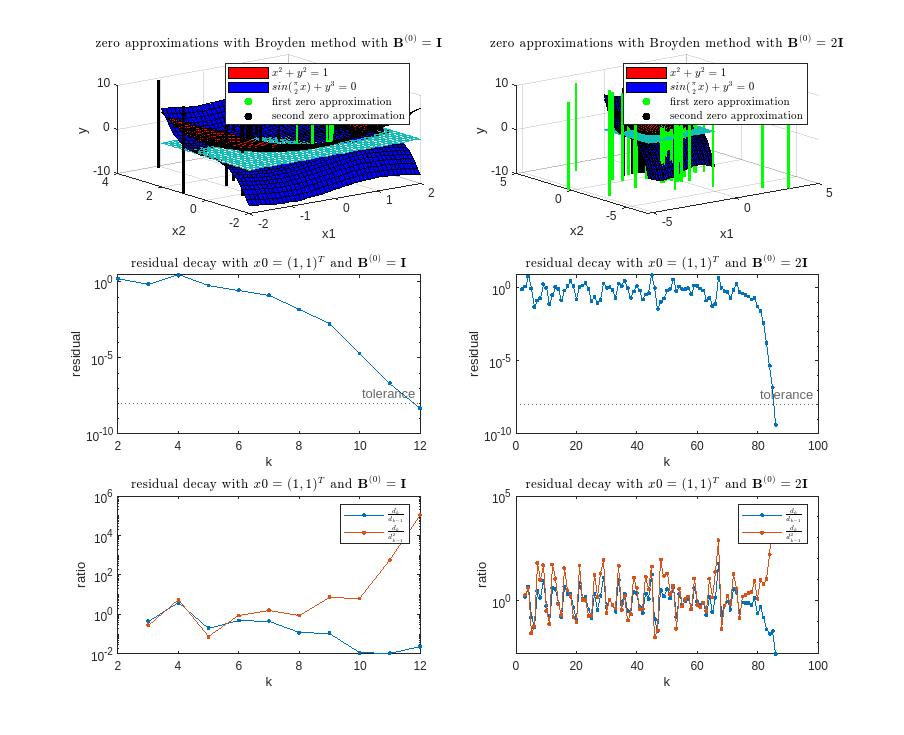

ratio1 = reA(2:end) ./ reA(1:end-1);
ratio1 = [Inf ratio1];

ratio2 = reA(2:end) ./ (reA(1:end-1) .^ 2);
ratio2 = [Inf ratio2];

subplot(3, 2, 6);
semilogy(1:length(ratio1), ratio1, '.-', ...
        1:length(ratio2), ratio2, '.-');
title(['residual decay with $x0 = (', ...
    num2str(x0A(1)), ', ', num2str(x0A(1)), ...
    ')^T$ and $\textbf{B}^{(0)} = 2\textbf{I}$' ...
    ], 'interpreter', 'latex');
legend('$\frac{d_k}{d_{k-1}}$', ...
        '$\frac{d_k}{d_{k-1}^2}$', ...
         'interpreter', 'latex');
xlabel("k"); ylabel("ratio");

Print results in a table

varNames = ["k", "increment (normalized)", "relative increment (normilized)", "ratio p = 1", "ratio p = 2"];
T = table((0:(kA - 1))', aeA', reA', ratio1', ratio2', 'VariableNames', varNames);
writetable(T, 'broydensys_B=2I_A.csv', 'Delimiter',';');

ratio1 = reB(2:end) ./ reB(1:end-1);
ratio1 = [Inf ratio1];

ratio2 = reB(2:end) ./ (reB(1:end-1) .^ 2);
ratio2 = [Inf ratio2];

varNames = ["k", "increment (normalized)", "relative increment (normilized)", "ratio p = 1", "ratio p = 2"];
T = table((0:(kB - 1))', aeB', reB', ratio1', ratio2', 'VariableNames', varNames);
writetable(T, 'broydensys_B=2I_B.csv', 'Delimiter',';');

 Log the final values

disp('zero approximations with Broyden method with B0 = 2I');

zero approximations with Broyden method with B0 = 2I


disp(['first zero = (', num2str(zeroA(1)), ', ', num2str(zeroA(2)), ...
    ') from x0 = (', num2str(x0A(1)), ', ', num2str(x0A(1)), ...
    ') with ', num2str(kA), ' iterations']);

first zero = (-0.4761, 0.87939) from x0 = (1, 1) with 86 iterations


disp(['second zero = (', num2str(zeroB(1)), ', ', num2str(zeroB(2)), ...
    ') from x0 = (', num2str(x0B(1)), ', ', num2str(x0B(1)), ...
    ') with ', num2str(kB), ' iterations']);

second zero = (-0.4761, 0.87939) from x0 = (-1, -1) with 12 iterations


## Appendix

#### Tested functions

function f = logistic_growth(t, pm, p0, K)
    f = pm / (1 + (pm / p0 - 1) * exp(-K * pm * t));
end

function f = logistic_growth_pm(pm, K, p0, t1, p1)
    f = p1 * (1 + (pm / p0 - 1) * exp(-K * pm * t1)) - pm;
end

function f = logistic_growth_pm_prime(pm, K, p0, t1, p1)
    f = (exp(-K * pm * t1) * (K * p1 * t1 * (p0 - pm) + p0 * (-exp(K * pm * t1)) + p1)) / p0;
end

#### Tested systems

function y = sys(x)
    y1 = x(1)^2 + x(2)^2 - 1;
    y2 = sin(pi/2 * x(1)) + x(2)^3;
    y = [y1; y2];
end

function J = jac(x)
    J(1, 1) = 2 * x(1);
    J(1, 2) = 2 * x(2);
    J(2, 1) = (pi/2) * cos(pi/2 * x(1));
    J(2, 2) = 3 * x(2)^2;
end